clc;
clear;
close


Image2 = imread('shopping-mall.png');
IGray2 = rgb_to_gray(Image2);
figure;
imshow(Image2);

hold on

% get the size of the img
[m,n]=size(IGray2);



#### Draw vanishing point

% initial VanishingPoint(middle of the Picture)
vb= .5 * (m);
va =.5 * (n);

% plot(va, vb,'r*')
pos_VanishingPoint = [va vb];
roi_VanishingPoint = images.roi.Point(gca,'Position',pos_VanishingPoint,"Color",'k',"LineWidth",5);
hold on

#### Draw inner rectangle

% [x y w h]= x and y elements determine the location (top-left) and the w and h elements determine the size
pos_InnerRectangle = [va-250,vb-250,500,500];
roi_InnerRectangle = drawrectangle('Color','k','FaceAlpha', 0, ...
    'FaceSelectable',(false),'LineWidth',1,'MarkerSize',8);
roi_InnerRectangle.Position = pos_InnerRectangle

roi_InnerRectangle =   Rectangle - 属性:

         Position: [569 774 500 500]
    RotationAngle: 0
      AspectRatio: 1
            Label: ''
            Color: [0 0 0]
           Parent: [1×1 Axes]
          Visible: on
         Selected: 0

  显示 所有属性

#### Draw 4 radial lines

r_top_left = [pos_InnerRectangle(1), pos_InnerRectangle(2)]

r_top_left =    569   774


r_top_right = [pos_InnerRectangle(1) + pos_InnerRectangle(3), pos_InnerRectangle(2)]

r_top_right =         1069         774


r_bottom_left = [pos_InnerRectangle(1), pos_InnerRectangle(2)+pos_InnerRectangle(4)]

r_bottom_left =          569        1274


r_botton_right = [pos_InnerRectangle(1)+pos_InnerRectangle(3), pos_InnerRectangle(2)+pos_InnerRectangle(4)]

r_botton_right =         1069        1274



roi_line1 = drawline('Position',[r_top_left;pos_VanishingPoint],'Color','r');
roi_line2 = drawline('Position',[r_top_right;pos_VanishingPoint],'Color','r');
roi_line3 = drawline('Position',[r_bottom_left;pos_VanishingPoint],'Color','r');
roi_line4 = drawline('Position',[r_botton_right;pos_VanishingPoint],'Color','r');



#### Get Positions of vanishing point & inner rectangle

 1. position of vanishing point

addlistener(roi_VanishingPoint,'MovingROI',@(src, evt) roiChange(src,evt,'Updated_VanishingPoint'));

2. position of inner rectangle

addlistener(roi_InnerRectangle,'MovingROI',@(src, evt) roiChange(src,evt,'Updated_InnerRectangle'));

 updated vertices of inner rectangle

Updated_InnerRectangle = 'Updated_InnerRectangle.mat';
save(Updated_InnerRectangle)

r_top_left = [Updated_InnerRectangle(1), Updated_InnerRectangle(2)]

r_top_left = 'Up'

r_top_right = [Updated_InnerRectangle(1) + Updated_InnerRectangle(3), Updated_InnerRectangle(2)]

r_top_right = '¹p'

r_bottom_left = [Updated_InnerRectangle(1), Updated_InnerRectangle(2)+Updated_InnerRectangle(4)]

r_bottom_left = 'UÑ'

r_botton_right = [Updated_InnerRectangle(1)+Updated_InnerRectangle(3), Updated_InnerRectangle(2)+Updated_InnerRectangle(4)]

r_botton_right =    185   209


 updated position of vanishing point

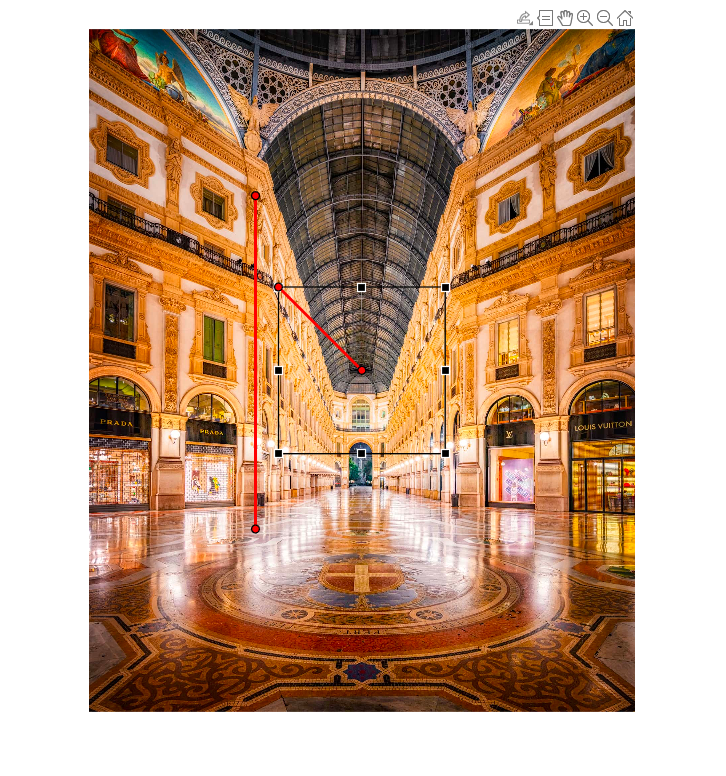

Updated_VanishingPoint = 'Updated_VanishingPoint.mat';
save(Updated_VanishingPoint)


% h = drawline('Position',[500 500;500 1500],'Color','r');

function roi = roiChange(~,evt,roi)
    assignin('base',roi,evt.CurrentPosition);

end


